# EXPERIMENTS - MULTICLASS

clear;
creditrating = readtable('CreditRating_Historical.dat');
addpath(['src'])
data = table2array(creditrating(:,2:end-1)); labels = table2array(creditrating(:,end));

% Convert to ratings to numeric values
Y = zeros(length(labels), 1);
for i = 1:length(labels)
    rating = labels{i};
    switch rating
        case 'AAA'
            Y(i) = 1;
        case 'AA'
            Y(i) = 2;
        case 'A'
            Y(i) = 3;
        case 'BBB'
            Y(i) = 4;
        case 'BB'
            Y(i) = 5;
        case 'B'
            Y(i) = 6;
        case 'CCC'
            Y(i) = 7;
    end
end

X = data;
n = length(Y);
X = X./(max(abs(X)));

ind = find(Y == 1 | Y == 2 | Y ==3| Y == 4 | Y == 5 | Y == 6 | Y == 7);
length(ind)

ans = 3932

X = X(ind,:);
Y = Y(ind,:);

id = randperm(length(Y), length(ind));
num = int16(n*0.4);
num_end = int16(n*0.5);
x_train = X(id(1:num),:);
x_test = X(id(num:num_end),:);
y_train = Y(id(1:num),:);
y_test = Y(id(num:num_end),:);

## Gaussian SMO

kType = 'gaussian'; kParam = 0.5; C = 100; eps = 1e-3; tol = 1e-3; maxIter = 400; verbose = 0;
G = formGramMatrix(x_train, kType, kParam);
smo.alphas = {};
smo.bs = {};
labels = unique(y_train);
for i = 1:length(labels)
    disp(i);
    y_temp = convert_labels(labels(i), y_train, num);
    [as, bs, info, K] = SMO(x_train, y_temp, C, kType, kParam, eps, tol, maxIter, verbose, G);
    smo.alphas{end+1} = as;
    smo.bs{end+1} = bs;
    disp(info.accValues)
end

     1



    0.9816



     2



    0.9002



     3



    0.8709



     4



    0.8125



     5



    0.8328



     6



    0.9263



     7



    0.9905



## Find test accuracy

num_test = length(y_test);
smo.matrix = zeros(7);
smo.preds = zeros(num_test, 1);
accuracy = 0;
for i = 1:num_test
    
    decision_values = zeros(length(labels), 1);
    for j = 1:length(labels)
        alphas = smo.alphas{j};
        bias = smo.bs{j};
        y_temp = convert_labels(labels(j), y_train, num);
        
        score = 0;
        for k = 1:num
            score = score + alphas(k)*y_temp(k)*K(x_train(k,:), x_test(i,:));
        end
        
        decision_values(j) = score - bias;
    end
    [value, label] = max(decision_values);
    smo.preds(i) = labels(label);
    if(labels(label) == y_test(i))
        accuracy = accuracy + 1;
    end
    smo.matrix(y_test(i), labels(label)) = smo.matrix(y_test(i), labels(label)) + 1;
end
accuracy/num_test

ans = 0.5863

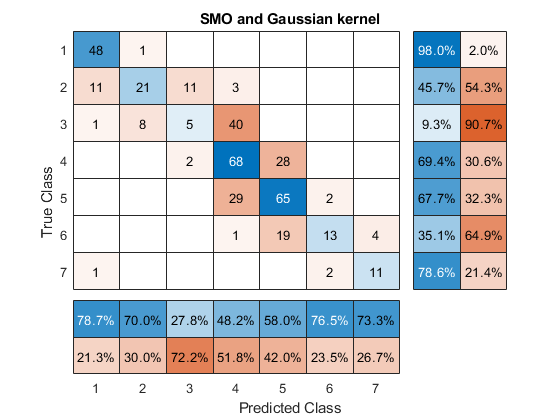

SAVE = false;
figure(1)
cm = confusionchart(y_test, smo.preds);
cm.Title = 'SMO and Gaussian kernel';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';


if SAVE
    saveas(1, './images/confusion_smo_gauss.png');
end

## Polynomial SMO

kType = 'poly'; kParam = 2; C = 10; eps = 1e-3; tol = 1e-3; maxIter = 400; verbose = 0;
G = formGramMatrix(x_train, kType, kParam);
smo_poly.alphas = {};
smo_poly.bs = {};
labels = unique(y_train);
for i = 1:length(labels)
    disp(i);
    y_temp = convert_labels(labels(i), y_train, num);
    [as, bs, info, K_poly] = SMO(x_train, y_temp, C, kType, kParam, eps, tol, maxIter, verbose, G);
    smo_poly.alphas{end+1} = as;
    smo_poly.bs{end+1} = bs;
    disp(info.accValues)
end

     1



    0.9415



     2



    0.8945



     3



    0.8665



     4



    0.7432



     5



    0.7718



     6



    0.9104



     7



    0.9847



## Find test accuracy

num_test = length(y_test);
smo_poly.preds = zeros(num_test, 1);
accuracy = 0;
for i = 1:num_test
    
    decision_values = zeros(length(labels), 1);
    for j = 1:length(labels)
        alphas = smo_poly.alphas{j};
        bias = smo_poly.bs{j};
        y_temp = convert_labels(labels(j), y_train, num);
        
        score = 0;
        for k = 1:num
            score = score + alphas(k)*y_temp(k)*K_poly(x_train(k,:), x_test(i,:));
        end
        
        decision_values(j) = score - bias;
    end
    [value, label] = max(decision_values);
    smo_poly.preds(i) = labels(label);
    if(labels(label) == y_test(i))
        accuracy = accuracy + 1;
    end
end
accuracy/num_test

ans = 0.5305

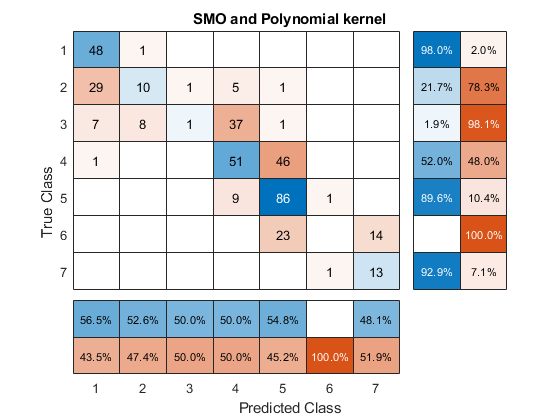

figure(2)

cm = confusionchart(y_test, smo_poly.preds);
cm.Title = 'SMO and Polynomial kernel';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';


if SAVE
    saveas(2, './images/confusion_barrier_poly.png');
end

## Barrier - Gaussian Kernel

kType = 'gaussian'; kParam = 0.05; C = 200; mu = 30; t = 0.001; maxIter = 60; verbose = 2;
G = formGramMatrix(x_train, kType, kParam);
barrier.alphas = {};
barrier.bs = {};
labels = unique(y_train);
for i = 1:length(labels)
    disp(i);
    y_temp = convert_labels(labels(i), y_train, num);
    [as, bs, info, K_barrier] = logBarrier(x_train, y_temp, C, mu, t, maxIter, kType, kParam, verbose, G);
    barrier.alphas{end+1} = as;
    barrier.bs{end+1} = bs;
    disp(info.accValues)
    disp(info.nIter)
end

## Find test accuracy

num_test = length(y_test);
barrier.preds = zeros(num_test, 1);
accuracy = 0;
for i = 1:num_test
    
    decision_values = zeros(length(labels), 1);
    for j = 1:length(labels)
        alphas = barrier.alphas{j};
        bias = barrier.bs{j};
        y_temp = convert_labels(labels(j), y_train, num);
        
        score = 0;
        for k = 1:num
            score = score + alphas(k)*y_temp(k)*K_barrier(x_train(k,:), x_test(i,:));
        end
        
        decision_values(j) = score + bias;
    end
    [value, label] = max(decision_values);
    barrier.preds(i) = labels(label);
    if(labels(label) == y_test(i))
        accuracy = accuracy + 1;
    end
end
accuracy/num_test

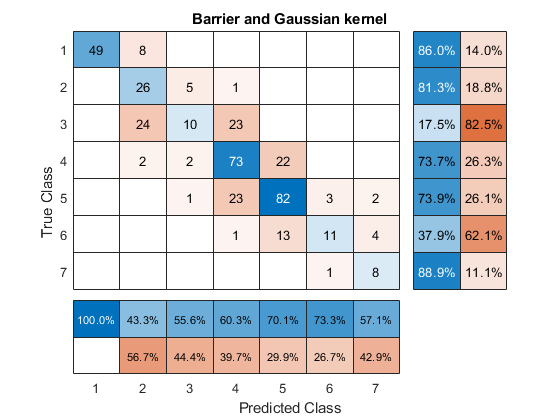

figure(3)
cm = confusionchart(y_test, barrier.preds);
cm.Title = 'Barrier and Gaussian kernel';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

if SAVE
    saveas(3, './images/confusion_barrier_gaussian.png');
end

## Polynomial Barrier

X = X./max(abs(X));

kType = 'poly'; kParam = 2; C = 100; mu = 10; t = 0.01; maxIter = 200; verbose = 2;
G = formGramMatrix(x_train, kType, kParam);
barrier_poly.alphas = {};
barrier_poly.bs = {};
labels = unique(y_train);
for i = 1:length(labels)
    disp(i);
    y_temp = convert_labels(labels(i), y_train, num);
    [as, bs, info, K_poly] = logBarrier(x_train, y_temp, C, mu, t, maxIter, kType, kParam, verbose, G);
    barrier_poly.alphas{end+1} = as;
    barrier_poly.bs{end+1} = bs;
    disp(info.accValues)
end

## Find test accuracy

num_test = length(y_test);
barrier_poly.preds = zeros(num_test, 1);
accuracy = 0;
for i = 1:num_test
    
    decision_values = zeros(length(labels), 1);
    for j = 1:length(labels)
        alphas = barrier_poly.alphas{j};
        bias = barrier_poly.bs{j};
        y_temp = convert_labels(labels(j), y_train, num);
        
        score = 0;
        for k = 1:num
            score = score + alphas(k)*y_temp(k)*K_poly(x_train(k,:), x_test(i,:));
        end
        
        decision_values(j) = score + bias;
    end
    [value, label] = max(decision_values);
    barrier_poly.preds(i) = labels(label);
    if(labels(label) == y_test(i))
        accuracy = accuracy + 1;
    end
end
accuracy/num_test

figure(4)

cm = confusionchart(y_test, barrier_poly.preds);
cm.Title = 'Barrier and Polynomial kernel';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

if SAVE
    saveas(4, './images/confusion_barrier_poly.png');
end